S = 1600;
Taper = 0.4;
b = 118;
Yehudi = 10;

Cr = S/(2*Yehudi+(1+Taper)/2*(b-2*Yehudi))

Cr = 18.0587

Ct = Cr*Taper

Ct = 7.2235

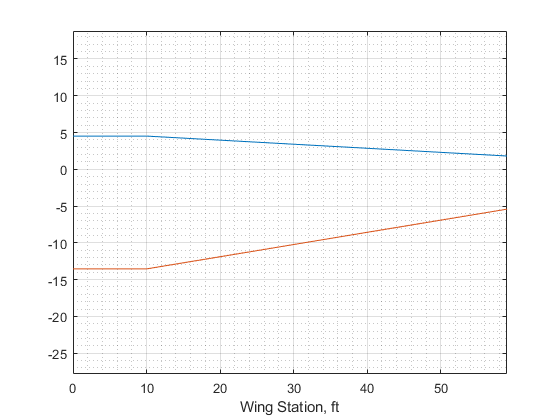


C = zeros(1,b/2);
Y = zeros(1,b/2);

C(1) = Cr;
Y(1) = 0;

for y=2:1:b/2
    
    Y(y) = y;
    
    if y<=Yehudi
        
        C(y) = Cr;
        
    else
        
        C(y) = Cr*(1-(1-Taper)*2*((y-Yehudi)/(b-2*Yehudi)));
        
    end
    
    
end

LE = C*0.25;

TE = -C*0.75;

plot (Y,LE)
hold on
plot (Y,TE)
hold off
axis equal
xlabel("Wing Station, ft");
grid on
grid minor